## Large-network Gamma - AEBE Coupling

#### 1.3. Experiment 2 Evoking gamma across 2 networks

#### Connectivity Pattern: coupled II across networks, double connection. 

Duration of simulation: 300 ms

       27915         600



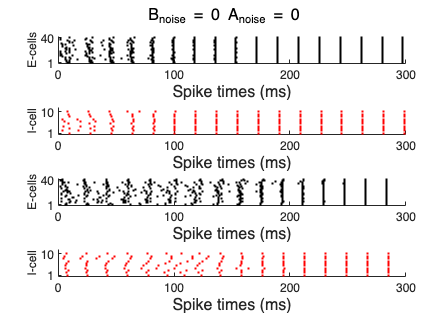

    0.1698



       25117         600



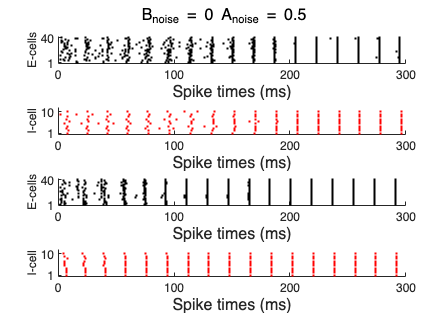

    0.1765



       30185         600



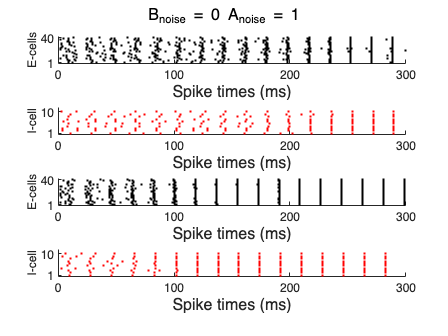

    0.1338



       28496         600



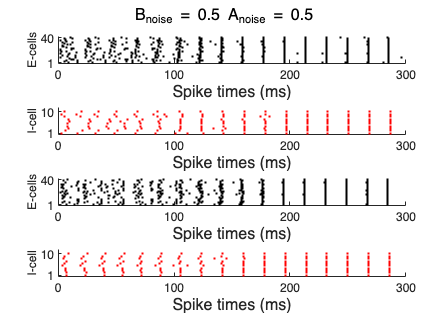

    0.1655



       27779         600



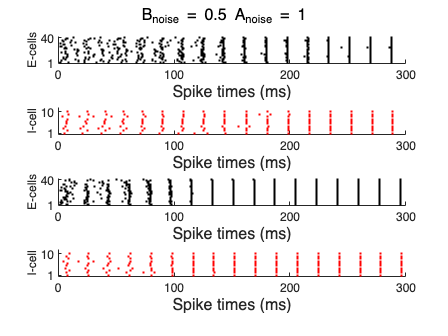

    0.1600



       25406         600



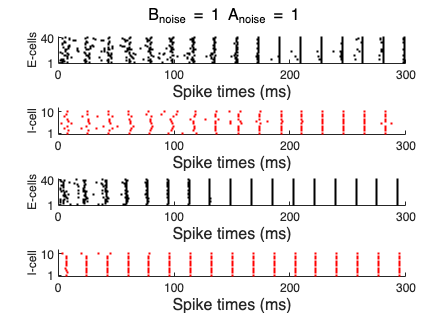

    0.1790



clearvars
% Instantiate variable for saving synchronization score 
strength = [1, 0.75, 0.5];
num_conditions = 6; % noise pairings 
syn_score_within_a = zeros(length(strength), num_conditions);
syn_score_within_b = zeros(length(strength), num_conditions);
syn_score_between = zeros(length(strength), num_conditions);

connectivity_scaling_within = [1,1,1,1];
connectivity_scaling_between = [0,0.5,0,0, 0,0.5,0,0];
tuples = [0,0;0,0.5;0,1;0.5,0.5;0.5,1;1,1];
for noise_i = 1:size(tuples, 1)
    rate_b = tuples(noise_i,1);
    rate_a = tuples(noise_i,2);
    clearvars -except syn_score_between syn_score_within_a syn_score_within_b connectivity_scaling_between connectivity_scaling_within tuples rate_a rate_b noise_i
    noise_pop='T';

    % (1) simulation time: 
    tstop = 300;  % Duration of simulation (msec)
    % (2) Define hh_param: for solving HodgkinHuxlkey Equations, using Na, K, l cahnnels and create the 
    GNa = 100;           % Maximum sodium current density (mS / cm^2)
    GK = 80;             % Maximum potassium current density (mS / cm^2)
    Gl = 0.1;            % Leak current density (mS / cm^2)
    vNa = 50;            % Reversal potential for sodium current (mV)
    vK = -100;           % Reversal potential for potassium current (mV)
    vl = -67;            % Reversal potential for leak current (mV)
    HH_param = [GNa GK Gl vNa vK vl];  % Load parameter vector
    % (3) Define syn_param
    Gei=0.2;   % Synaptic strength E-I, default 0.2
    Gie=0.2;   % Synaptic strength I-E, default 0.2
    Gee=0;     % Synaptic strength E-E, default 0
    Gii=0;     % Synaptic strength I-I, default 0
    vampa=0;   % reversal potential ampa (noisy input, default 0)
    vgaba=-80; % reversal potential gaba (default -80)
    syn_param=[Gei Gie Gee Gii vampa vgaba];
    % (4) Define stim_param: applied current to inhib and exc cells. Assume inh and exc
    % applied currents get activated at the same time. 
    del = 0;
    dur = tstop;            % Duration of stimulus (msec)
    amp_i= 0.5;             % applied current to the i cells, default 0.5
    stim_param_i = [del dur amp_i];  % Load parameter vector
    amp_e=2.0;              %applied current to the e cells, default 2.0
    stim_param_e = [del dur amp_e];  % Load parameter vector
    % (5) Set Connectivity, Connectivity Strength, External Drive, Simulation Duration
    load('connectivity_100cell_1_1_EE0.5.mat') % this file actually contains 100 cells
    
    % (6) n, num_exc, num_inh
    n = 100;
    num_exc = 40; %determines number of I cells
    num_inh = 10;
    %--- Compute variables using hh_integrate_network_noise
    [t,x] = hh_integrate_network_noise_net(tstop, HH_param, syn_param, stim_param_i, stim_param_e,...
        connectivity_grid,connectivity_scaling_within,connectivity_scaling_between,n,rate_a, rate_b, noise_pop);
    disp(size(x));

    [m, n] = size(x);
    AE = zeros(m, num_exc);  % Initialize E with zeros (or any other value)
    AI = zeros(m, num_inh);  % Initialize I with zeros (or any other value)
    AE = x(:,1:num_exc); % pop AE
    AI = x(:, (num_exc + 1):n); % pop AI
    
    BE = zeros(m, num_exc);  % Initialize E with zeros (or any other value)
    BI = zeros(m, num_inh);  % Initialize I with zeros (or any other value)
    BE = x(:,51:num_exc+50); % pop BE
    BI = x(:, (num_exc + 51):n); % pop BI
    
    % ------------------- Plotting & Spikes for synchronization score ----%
    
    figure
    %E cell spiking
    subplot(4,1,1)
    hold on
    Espike_count=0; %will be used to calculate spike rate later
    e_count=0; %counts the number of e_cells that actually fire
    spike_mat_ae = zeros(num_exc, 25); % hard-coded spike mat, assumes maximum 25 spikes 
    for i = 1:num_exc % for each exc cell
        if max(AE(:,i))>0
            [pks,locs] = findpeaks(AE(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
            % ------------ populate spiking matrix ----------%
            num_spikes = length(locs);
            spike_mat_ae(i,1:num_spikes) = locs/100;
            % ------------ do the plotting ------------------%
            plot(t(locs),i,'k.') %cell index vs time of spike
            % index t wth locs, only scatter on those locations for this cell,
            Espike_count=Espike_count+length(pks);
            e_count=e_count+1;
        end
    end
    axis([0 tstop .5 num_exc+2])
    set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
    set(gca,'Ytick',1:num_exc-1:num_exc)
    xlabel('Spike times (ms)','Fontsize',20);
    ylabel('E-cells','Fontsize',15)
    
    %I cell spiking
    subplot(4,1,2)
    hold on
    Ispike_count=0; %used to calculate spike rate later
    i_spike=0; %counts the number of i cells that actually spike
    for i = 1:num_inh
        if max(AI(:,i))>0
            [pks,locs] = findpeaks(AI(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
            plot(t(locs),i,'r.')
            Ispike_count=Ispike_count+length(pks);
            i_spike=i_spike+1;
        end
    end
    axis([0 tstop .5 num_inh+2])
    set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
    set(gca,'Ytick',1:num_inh-1:num_inh)
    xlabel('Spike times (ms)','Fontsize',20);
    ylabel('I-cell','Fontsize',15)
    
    %E cell spiking
    subplot(4,1,3)
    hold on
    Espike_count=0; %will be used to calculate spike rate later
    e_count=0; %counts the number of e_cells that actually fire
    spike_mat_be = zeros(num_exc, 25);
    for i = 1:num_exc % for each exc cell
        if max(BE(:,i))>0
            [pks,locs] = findpeaks(BE(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
            plot(t(locs),i,'k.') %plots cell index vs time of spike
            % ------------ populate spiking matrix ----------%
            num_spikes = length(locs);
            spike_mat_be(i,1:num_spikes) = locs/100;
            % ------------ do the plotting ------------------%
            % index t wth locs, only scatter on those locations for this cell,
            % helps with aligning with the absolute timeframe 
            Espike_count=Espike_count+length(pks);
            e_count=e_count+1;
        end
    end
    axis([0 tstop .5 num_exc+2])
    set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
    set(gca,'Ytick',1:num_exc-1:num_exc)
    xlabel('Spike times (ms)','Fontsize',20);
    ylabel('E-cells','Fontsize',15)
    
    %I cell spiking
    subplot(4,1,4)
    hold on
    Ispike_count=0; %used to calculate spike rate later
    i_spike=0; %counts the number of i cells that actually spike
    for i = 1:num_inh
        if max(BI(:,i))>0
            [pks,locs] = findpeaks(BI(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
            plot(t(locs),i,'r.')
            Ispike_count=Ispike_count+length(pks);
            i_spike=i_spike+1;
        end
    end
    axis([0 tstop .5 num_inh+2])
    set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
    set(gca,'Ytick',1:num_inh-1:num_inh)
    xlabel('Spike times (ms)','Fontsize',20);
    ylabel('I-cell','Fontsize',15);
    sgtitle("B_{noise} = " + rate_b + " A_{noise} = " + rate_a, 'Fontsize', 20);

    %average spike rate across neurons for this entire period 
    Avg_freq_E = (Espike_count/num_exc)*(1000/tstop);
    Avg_freq_I = (Ispike_count/num_inh)*(1000/tstop);
    
    %------------------- Calc synchronization score and store ------%
    T = ceil(m/100);
    S_ae_bar = mean(spike_mat_ae);
    S_be_bar = mean(spike_mat_be);
    S = cat(1,S_ae_bar,S_be_bar);
    S_bet = SpikeContrast(spike_mat_ae, T); 
    disp(S_bet);

    syn_score_between(1,noise_i) = S_bet;
end

% --------------------------------------------------------------------------------- %
connectivity_scaling_within = [1,1,1,1];
connectivity_scaling_between = [0,0.75,0,0,0,0.75,0,0];
tuples = [0,0;0,0.5;0,1;0.5,0.5;0.5,1;1,1]

for noise_i = 1:size(tuples, 1)
    rate_b = tuples(noise_i,1);
    rate_a = tuples(noise_i,2);
    clearvars -except syn_score_between syn_score_within_a syn_score_within_b connectivity_scaling_between connectivity_scaling_within tuples rate_a rate_b noise_i
    noise_pop='T';

tuples =          0         0
         0    0.5000
         0    1.0000
    0.5000    0.5000
    0.5000    1.0000
    1.0000    1.0000


       29769         600



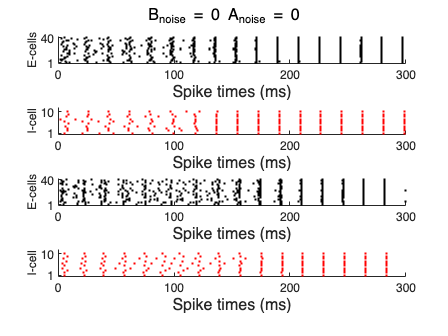

    0.1339



       28974         600



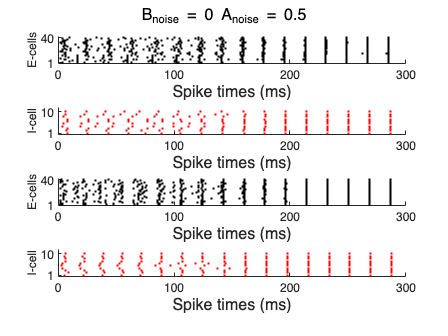

    0.1506



       22678         600



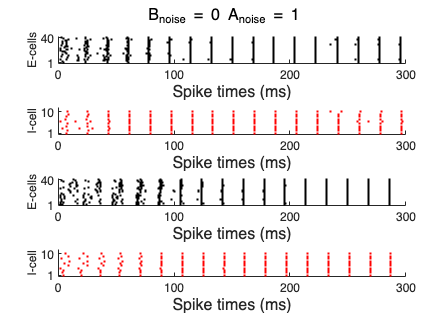

    0.1938



       31170         600



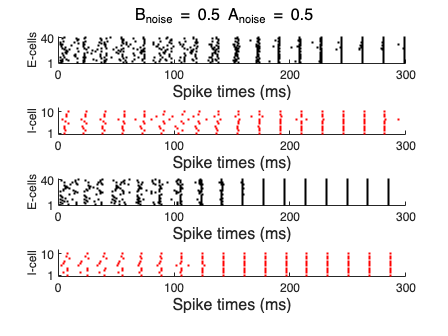

    0.1469



       23165         600



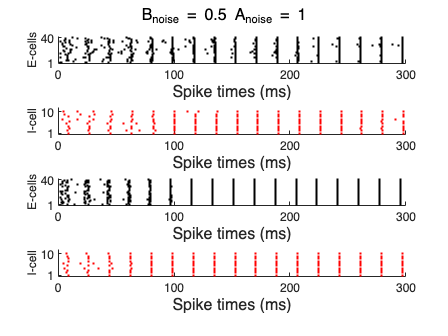

    0.1798



       30953         600



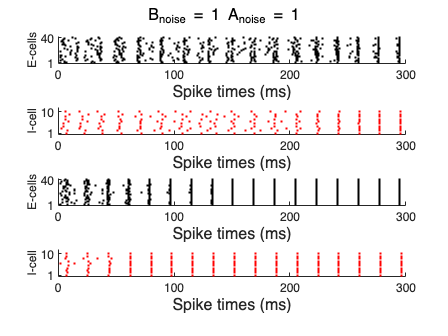

    0.1297




    % (1) simulation time: 
    tstop = 300;  % Duration of simulation (msec)
    % (2) Define hh_param: for solving HodgkinHuxlkey Equations, using Na, K, l cahnnels and create the 
    GNa = 100;           % Maximum sodium current density (mS / cm^2)
    GK = 80;             % Maximum potassium current density (mS / cm^2)
    Gl = 0.1;            % Leak current density (mS / cm^2)
    vNa = 50;            % Reversal potential for sodium current (mV)
    vK = -100;           % Reversal potential for potassium current (mV)
    vl = -67;            % Reversal potential for leak current (mV)
    HH_param = [GNa GK Gl vNa vK vl];  % Load parameter vector
    % (3) Define syn_param
    Gei=0.2;   % Synaptic strength E-I, default 0.2
    Gie=0.2;   % Synaptic strength I-E, default 0.2
    Gee=0;     % Synaptic strength E-E, default 0
    Gii=0;     % Synaptic strength I-I, default 0
    vampa=0;   % reversal potential ampa (noisy input, default 0)
    vgaba=-80; % reversal potential gaba (default -80)
    syn_param=[Gei Gie Gee Gii vampa vgaba];
    % (4) Define stim_param: applied current to inhib and exc cells. Assume inh and exc
    % applied currents get activated at the same time. 
    del = 0;
    dur = tstop;            % Duration of stimulus (msec)
    amp_i= 0.5;             % applied current to the i cells, default 0.5
    stim_param_i = [del dur amp_i];  % Load parameter vector
    amp_e=2.0;              %applied current to the e cells, default 2.0
    stim_param_e = [del dur amp_e];  % Load parameter vector
    % (5) Set Connectivity, Connectivity Strength, External Drive, Simulation Duration
    load('connectivity_100cell_1_1_EE0.75.mat') % this file actually contains 100 cells
    
    % (6) n, num_exc, num_inh
    n = 100;
    num_exc = 40; %determines number of I cells
    num_inh = 10;
    %--- Compute variables using hh_integrate_network_noise
    [t,x] = hh_integrate_network_noise_net(tstop, HH_param, syn_param, stim_param_i, stim_param_e,...
        connectivity_grid,connectivity_scaling_within,connectivity_scaling_between,n,rate_a, rate_b, noise_pop);
    disp(size(x));

    [m, n] = size(x);
    AE = zeros(m, num_exc);  % Initialize E with zeros (or any other value)
    AI = zeros(m, num_inh);  % Initialize I with zeros (or any other value)
    AE = x(:,1:num_exc); % pop AE
    AI = x(:, (num_exc + 1):n); % pop AI
    
    BE = zeros(m, num_exc);  % Initialize E with zeros (or any other value)
    BI = zeros(m, num_inh);  % Initialize I with zeros (or any other value)
    BE = x(:,51:num_exc+50); % pop BE
    BI = x(:, (num_exc + 51):n); % pop BI
    
    % ------------------- Plotting & Spikes for synchronization score ----%
    
    figure
    %E cell spiking
    subplot(4,1,1)
    hold on
    Espike_count=0; %will be used to calculate spike rate later
    e_count=0; %counts the number of e_cells that actually fire
    spike_mat_ae = zeros(num_exc, 25); % hard-coded spike mat, assumes maximum 25 spikes 
    for i = 1:num_exc % for each exc cell
        if max(AE(:,i))>0
            [pks,locs] = findpeaks(AE(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
            % ------------ populate spiking matrix ----------%
            num_spikes = length(locs);
            spike_mat_ae(i,1:num_spikes) = locs/100;
            % ------------ do the plotting ------------------%
            plot(t(locs),i,'k.') %cell index vs time of spike
            % index t wth locs, only scatter on those locations for this cell,
            Espike_count=Espike_count+length(pks);
            e_count=e_count+1;
        end
    end
    axis([0 tstop .5 num_exc+2])
    set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
    set(gca,'Ytick',1:num_exc-1:num_exc)
    xlabel('Spike times (ms)','Fontsize',20);
    ylabel('E-cells','Fontsize',15)
    
    %I cell spiking
    subplot(4,1,2)
    hold on
    Ispike_count=0; %used to calculate spike rate later
    i_spike=0; %counts the number of i cells that actually spike
    for i = 1:num_inh
        if max(AI(:,i))>0
            [pks,locs] = findpeaks(AI(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
            plot(t(locs),i,'r.')
            Ispike_count=Ispike_count+length(pks);
            i_spike=i_spike+1;
        end
    end
    axis([0 tstop .5 num_inh+2])
    set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
    set(gca,'Ytick',1:num_inh-1:num_inh)
    xlabel('Spike times (ms)','Fontsize',20);
    ylabel('I-cell','Fontsize',15)
    
    %E cell spiking
    subplot(4,1,3)
    hold on
    Espike_count=0; %will be used to calculate spike rate later
    e_count=0; %counts the number of e_cells that actually fire
    spike_mat_be = zeros(num_exc, 25);
    for i = 1:num_exc % for each exc cell
        if max(BE(:,i))>0
            [pks,locs] = findpeaks(BE(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
            plot(t(locs),i,'k.') %plots cell index vs time of spike
            % ------------ populate spiking matrix ----------%
            num_spikes = length(locs);
            spike_mat_be(i,1:num_spikes) = locs/100;
            % ------------ do the plotting ------------------%
            % index t wth locs, only scatter on those locations for this cell,
            % helps with aligning with the absolute timeframe 
            Espike_count=Espike_count+length(pks);
            e_count=e_count+1;
        end
    end
    axis([0 tstop .5 num_exc+2])
    set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
    set(gca,'Ytick',1:num_exc-1:num_exc)
    xlabel('Spike times (ms)','Fontsize',20);
    ylabel('E-cells','Fontsize',15)
    
    %I cell spiking
    subplot(4,1,4)
    hold on
    Ispike_count=0; %used to calculate spike rate later
    i_spike=0; %counts the number of i cells that actually spike
    for i = 1:num_inh
        if max(BI(:,i))>0
            [pks,locs] = findpeaks(BI(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
            plot(t(locs),i,'r.')
            Ispike_count=Ispike_count+length(pks);
            i_spike=i_spike+1;
        end
    end
    axis([0 tstop .5 num_inh+2])
    set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
    set(gca,'Ytick',1:num_inh-1:num_inh)
    xlabel('Spike times (ms)','Fontsize',20);
    ylabel('I-cell','Fontsize',15);
    sgtitle("B_{noise} = " + rate_b + " A_{noise} = " + rate_a, 'Fontsize', 20);

    %average spike rate across neurons for this entire period 
    Avg_freq_E = (Espike_count/num_exc)*(1000/tstop);
    Avg_freq_I = (Ispike_count/num_inh)*(1000/tstop);
    
    %------------------- Calc synchronization score and store ------%
    T = ceil(m/100);
    S_ae_bar = mean(spike_mat_ae);
    S_be_bar = mean(spike_mat_be);
    S = cat(1,S_ae_bar,S_be_bar);
    S_bet = SpikeContrast(spike_mat_ae, T); 
    disp(S_bet);

    syn_score_between(2,noise_i) = S_bet;
end


% --------------------------------------------------------------------------------- %
connectivity_scaling_within = [1,1,1,1];
connectivity_scaling_between = [0,1,0,0, 0,1,0,0];

tuples = [0,0;0,0.5;0,1;0.5,0.5;0.5,1;1,1]
for noise_i = 1:size(tuples, 1)
    rate_b = tuples(noise_i,1);
    rate_a = tuples(noise_i,2);
    clearvars -except syn_score_between syn_score_within_a syn_score_within_b connectivity_scaling_between connectivity_scaling_within tuples rate_a rate_b noise_i
    noise_pop='T';

tuples =          0         0
         0    0.5000
         0    1.0000
    0.5000    0.5000
    0.5000    1.0000
    1.0000    1.0000


       19654         600



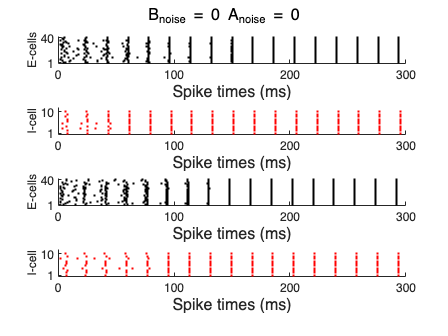

    0.2202



       19498         600



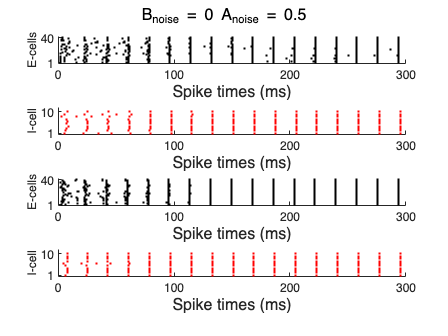

    0.2282



       18899         600



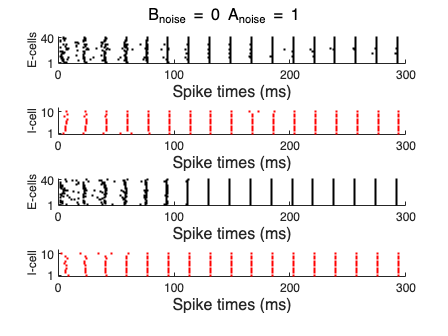

    0.2289



       21279         600



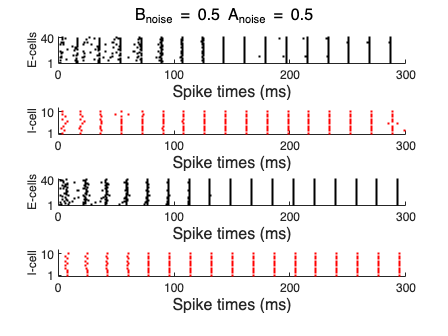

    0.1899



       23398         600



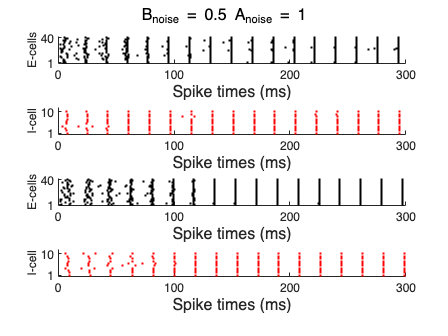

    0.1775



       31877         600



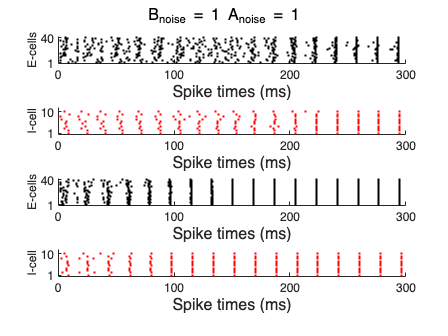

    0.1343




    % (1) simulation time: 
    tstop = 300;  % Duration of simulation (msec)
    % (2) Define hh_param: for solving HodgkinHuxlkey Equations, using Na, K, l cahnnels and create the 
    GNa = 100;           % Maximum sodium current density (mS / cm^2)
    GK = 80;             % Maximum potassium current density (mS / cm^2)
    Gl = 0.1;            % Leak current density (mS / cm^2)
    vNa = 50;            % Reversal potential for sodium current (mV)
    vK = -100;           % Reversal potential for potassium current (mV)
    vl = -67;            % Reversal potential for leak current (mV)
    HH_param = [GNa GK Gl vNa vK vl];  % Load parameter vector
    % (3) Define syn_param
    Gei=0.2;   % Synaptic strength E-I, default 0.2
    Gie=0.2;   % Synaptic strength I-E, default 0.2
    Gee=0;     % Synaptic strength E-E, default 0
    Gii=0;     % Synaptic strength I-I, default 0
    vampa=0;   % reversal potential ampa (noisy input, default 0)
    vgaba=-80; % reversal potential gaba (default -80)
    syn_param=[Gei Gie Gee Gii vampa vgaba];
    % (4) Define stim_param: applied current to inhib and exc cells. Assume inh and exc
    % applied currents get activated at the same time. 
    del = 0;
    dur = tstop;            % Duration of stimulus (msec)
    amp_i= 0.5;             % applied current to the i cells, default 0.5
    stim_param_i = [del dur amp_i];  % Load parameter vector
    amp_e=2.0;              %applied current to the e cells, default 2.0
    stim_param_e = [del dur amp_e];  % Load parameter vector
    % (5) Set Connectivity, Connectivity Strength, External Drive, Simulation Duration
    load('connectivity_100cell_1_1_EE1.mat');
    
    % (6) n, num_exc, num_inh
    n = 100;
    num_exc = 40; %determines number of I cells
    num_inh = 10;
    %--- Compute variables using hh_integrate_network_noise
    [t,x] = hh_integrate_network_noise_net(tstop, HH_param, syn_param, stim_param_i, stim_param_e,...
        connectivity_grid,connectivity_scaling_within,connectivity_scaling_between,n,rate_a, rate_b, noise_pop);
    disp(size(x));

    [m, n] = size(x);
    AE = zeros(m, num_exc);  % Initialize E with zeros (or any other value)
    AI = zeros(m, num_inh);  % Initialize I with zeros (or any other value)
    AE = x(:,1:num_exc); % pop AE
    AI = x(:, (num_exc + 1):n); % pop AI
    
    BE = zeros(m, num_exc);  % Initialize E with zeros (or any other value)
    BI = zeros(m, num_inh);  % Initialize I with zeros (or any other value)
    BE = x(:,51:num_exc+50); % pop BE
    BI = x(:, (num_exc + 51):n); % pop BI
    
    % ------------------- Plotting & Spikes for synchronization score ----%
    
    figure
    %E cell spiking
    subplot(4,1,1)
    hold on
    Espike_count=0; %will be used to calculate spike rate later
    e_count=0; %counts the number of e_cells that actually fire
    spike_mat_ae = zeros(num_exc, 25); % hard-coded spike mat, assumes maximum 25 spikes 
    for i = 1:num_exc % for each exc cell
        if max(AE(:,i))>0
            [pks,locs] = findpeaks(AE(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
            % ------------ populate spiking matrix ----------%
            num_spikes = length(locs);
            spike_mat_ae(i,1:num_spikes) = locs/100;
            % ------------ do the plotting ------------------%
            plot(t(locs),i,'k.') %cell index vs time of spike
            % index t wth locs, only scatter on those locations for this cell,
            Espike_count=Espike_count+length(pks);
            e_count=e_count+1;
        end
    end
    axis([0 tstop .5 num_exc+2])
    set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
    set(gca,'Ytick',1:num_exc-1:num_exc)
    xlabel('Spike times (ms)','Fontsize',20);
    ylabel('E-cells','Fontsize',15)
    
    %I cell spiking
    subplot(4,1,2)
    hold on
    Ispike_count=0; %used to calculate spike rate later
    i_spike=0; %counts the number of i cells that actually spike
    for i = 1:num_inh
        if max(AI(:,i))>0
            [pks,locs] = findpeaks(AI(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
            plot(t(locs),i,'r.')
            Ispike_count=Ispike_count+length(pks);
            i_spike=i_spike+1;
        end
    end
    axis([0 tstop .5 num_inh+2])
    set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
    set(gca,'Ytick',1:num_inh-1:num_inh)
    xlabel('Spike times (ms)','Fontsize',20);
    ylabel('I-cell','Fontsize',15)
    
    %E cell spiking
    subplot(4,1,3)
    hold on
    Espike_count=0; %will be used to calculate spike rate later
    e_count=0; %counts the number of e_cells that actually fire
    spike_mat_be = zeros(num_exc, 25);
    for i = 1:num_exc % for each exc cell
        if max(BE(:,i))>0
            [pks,locs] = findpeaks(BE(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
            plot(t(locs),i,'k.') %plots cell index vs time of spike
            % ------------ populate spiking matrix ----------%
            num_spikes = length(locs);
            spike_mat_be(i,1:num_spikes) = locs/100;
            % ------------ do the plotting ------------------%
            % index t wth locs, only scatter on those locations for this cell,
            % helps with aligning with the absolute timeframe 
            Espike_count=Espike_count+length(pks);
            e_count=e_count+1;
        end
    end
    axis([0 tstop .5 num_exc+2])
    set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
    set(gca,'Ytick',1:num_exc-1:num_exc)
    xlabel('Spike times (ms)','Fontsize',20);
    ylabel('E-cells','Fontsize',15)
    
    %I cell spiking
    subplot(4,1,4)
    hold on
    Ispike_count=0; %used to calculate spike rate later
    i_spike=0; %counts the number of i cells that actually spike
    for i = 1:num_inh
        if max(BI(:,i))>0
            [pks,locs] = findpeaks(BI(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
            plot(t(locs),i,'r.')
            Ispike_count=Ispike_count+length(pks);
            i_spike=i_spike+1;
        end
    end
    axis([0 tstop .5 num_inh+2])
    set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
    set(gca,'Ytick',1:num_inh-1:num_inh)
    xlabel('Spike times (ms)','Fontsize',20);
    ylabel('I-cell','Fontsize',15);
    sgtitle("B_{noise} = " + rate_b + " A_{noise} = " + rate_a, 'Fontsize', 20);

    %average spike rate across neurons for this entire period 
    Avg_freq_E = (Espike_count/num_exc)*(1000/tstop);
    Avg_freq_I = (Ispike_count/num_inh)*(1000/tstop);
    
    %------------------- Calc synchronization score and store ------%
    T = ceil(m/100);
    S_ae_bar = mean(spike_mat_ae);
    S_be_bar = mean(spike_mat_be);
    S = cat(1,S_ae_bar,S_be_bar);
    S_bet = SpikeContrast(spike_mat_ae, T); 
    disp(S_bet);

    syn_score_between(3,noise_i) = S_bet;
end


% -------------- display the populated plot ---------%
disp(syn_score_between);

    0.1698    0.1765    0.1338    0.1655    0.1600    0.1790
    0.1339    0.1506    0.1938    0.1469    0.1798    0.1297
    0.2202    0.2282    0.2289    0.1899    0.1775    0.1343



% Define the data for six groups
group1 = syn_score_between(:,1)';     % Values for Group 1
group2 = syn_score_between(:,2)';      % Values for Group 2
group3 = syn_score_between(:,3)';   % Values for Group 3
group4 = syn_score_between(:,4)';     % Values for Group 4
group5 = syn_score_between(:,5)';    % Values for Group 5
group6 = syn_score_between(:,6)';  % Values for Group 6
disp(group2);

    0.1765    0.1506    0.2282



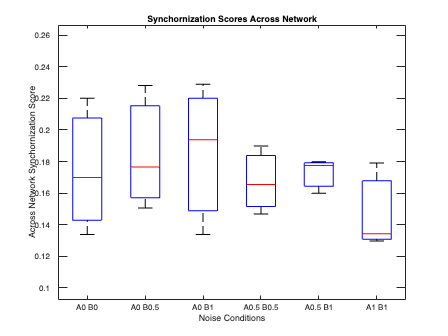

% Combine the groups into a single matrix
data = [group1; group2; group3; group4; group5; group6]';  
% Create a boxplot
figure;  % Create a new figure window
boxplot(data);  % Create the boxplot
xlabel('Noise Conditions');  % Label for the x-axis
ylabel('Across Network Synchornization Score');  % Label for the y-axis
title('Synchornization Scores Across Network');  % Title of the boxplot
% Set custom x-tick labels
set(gca, 'XTick', 1:6, 'XTickLabel', {'A0 B0', 'A0 B0.5', 'A0 B1', 'A0.5 B0.5', 'A0.5 B1', 'A1 B1'});